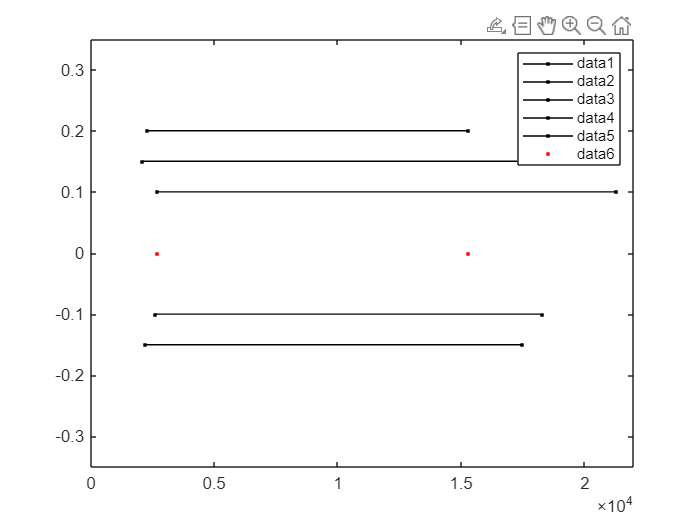

tInterval = [2598 18299];
tInterva2 = [2298 15299];
tInterva3 = [2698 21299];
tInterva4 = [2198 17499];
tInterva5 = [2098 17599];

tResult = [2698 15299];

plot(tInterval,[-0.1 -0.1],'k.-');
hold on;
plot(tInterva5,[0.15 0.15],'k.-');
plot(tInterva2,[0.2 0.2],'k.-');
plot(tInterva3,[0.1 0.1],'k.-');
plot(tInterva4,[-0.15 -0.15],'k.-');
plot(tResult,[0 0],'r.-',"LineWidth",3);
axis([0 22000 -0.35 0.35])
legend;

## find highest in first col, and lowest in 2nd col

% Given list
testSortList = ["record04_light.csv","record02_light.csv", "record05_mm.csv","record04_mm.csv", "record02_mm.csv", "record03_moderate.csv", "record02_off.csv", "record01_light.csv", "record01_mm.csv", "record02_off.csv", "record02_light.csv", "record01_moderate.csv", "record01_off.csv"];

% Extract numbers from the filenames
extractedNumbers = regexp(testSortList, '\d+', 'match');

Unrecognized function or variable 'testSortList'.

flattenedNumbers = string([extractedNumbers{:}]);

% Sort the original list based on the extracted numbers
[sortedNumbers, sortIndex] = sort(flattenedNumbers);
sortedList = testSortList(sortIndex);

% Find unique numbers and their first occurrence index
[uniqueNumbers, firstOccurrenceIndex] = unique(sortedNumbers, 'stable');

% Initialize start and end indices arrays
startIndices = firstOccurrenceIndex;
endIndices = [firstOccurrenceIndex(2:end)-1; numel(sortedList)]; % Shift and append for end indices

intervalMatrix = [startIndices, endIndices]; %each interval show the start and end point of a sequence for interval creation

goal is to create 5 intervals. 

each interval stands for its unique record 

we find intervals with cropSignals. we would not need to include signals coming from the folder "mm", since this should have no video contacts anyway




% Display the sorted list, unique numbers, and their start/end indices
disp('Sorted List:');
disp(sortedList);
disp('Unique Numbers:');
disp(uniqueNumbers);
disp('Start Indices:');
disp(startIndices);
disp('End Indices:');
disp(endIndices);
startIndices(end+1) = NaN; %set NaN Flag
intervals = zeros(numel(uniqueNumbers),2);

for idx = 1:length(startIndices)
    intervals = [];
    %check if the last index is NaN
    %nan flags arrays end
    if isnan(startIndices(idx+1))
        disp("end here")  
        break;
    %check if an entry is only 1 counter away from the next
    %entry. 
    elseif  startIndices(idx+1) == startIndices(idx)+1
        disp("stopped here for single uniques");
        disp(idx);        
    else 
        intervals(idx,1) = startIndices(idx);  
        intervals(idx,2) = startIndices(idx+1)-1;
    end
end


% TestSortedList  = sort(testSortList);